**Data**

x = [10    20    30    40    50    60    70    80    90   100]

x =     10    20    30    40    50    60    70    80    90   100



y = [0.18    0.29    0.32    0.39    0.40    0.41    0.43    0.47    0.47    0.47]

y =     0.1800    0.2900    0.3200    0.3900    0.4000    0.4100    0.4300    0.4700    0.4700    0.4700


**Plot data**

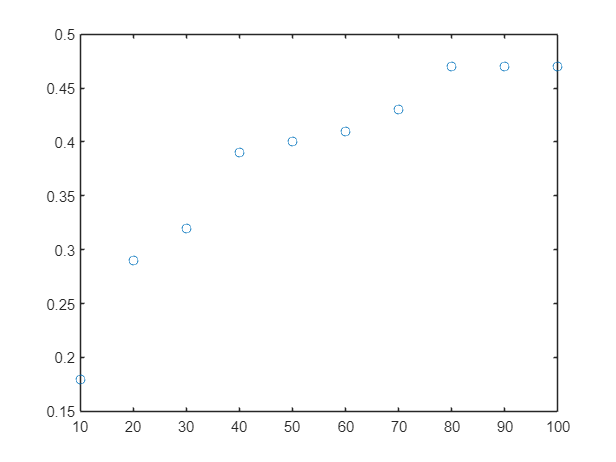

plot(x,y,"o")

**Transform data**

newx = 1./x

newx =     0.1000    0.0500    0.0333    0.0250    0.0200    0.0167    0.0143    0.0125    0.0111    0.0100


newy = 1./y

newy =     5.5556    3.4483    3.1250    2.5641    2.5000    2.4390    2.3256    2.1277    2.1277    2.1277


**Perform linear regression & plot dataset + fitted line**

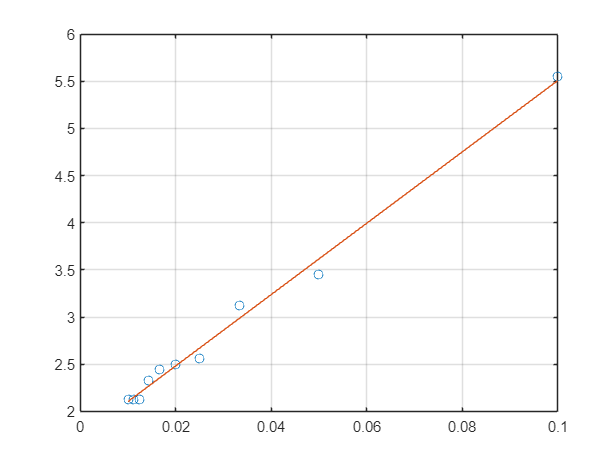

a =    37.8012    1.7269


r2 = 0.9922

[a,r2] = linregr(newx,newy)

**Computer parameters of nonlinear equation from the fitted line**

alpha = 1./a(2)

alpha = 0.5791

beta = a(1)*alpha

beta = 21.8901

**Plot the original data with the best fit nonlinear curve**

xx = 0 : 0.1 : 100

xx =          0    0.1000    0.2000    0.3000    0.4000    0.5000    0.6000    0.7000    0.8000    0.9000    1.0000    1.1000    1.2000    1.3000    1.4000    1.5000    1.6000    1.7000    1.8000    1.9000    2.0000    2.1000    2.2000    2.3000    2.4000    2.5000    2.6000    2.7000    2.8000    2.9000    3.0000    3.1000    3.2000    3.3000    3.4000    3.5000    3.6000    3.7000    3.8000    3.9000    4.0000    4.1000    4.2000    4.3000    4.4000    4.5000    4.6000    4.7000    4.8000    4.9000


yy = alpha .* xx./(beta+xx)

yy =          0    0.0026    0.0052    0.0078    0.0104    0.0129    0.0154    0.0179    0.0204    0.0229    0.0253    0.0277    0.0301    0.0325    0.0348    0.0371    0.0394    0.0417    0.0440    0.0462    0.0485    0.0507    0.0529    0.0551    0.0572    0.0594    0.0615    0.0636    0.0657    0.0677    0.0698    0.0718    0.0739    0.0759    0.0779    0.0798    0.0818    0.0837    0.0857    0.0876    0.0895    0.0914    0.0932    0.0951    0.0969    0.0987    0.1006    0.1024    0.1041    0.1059


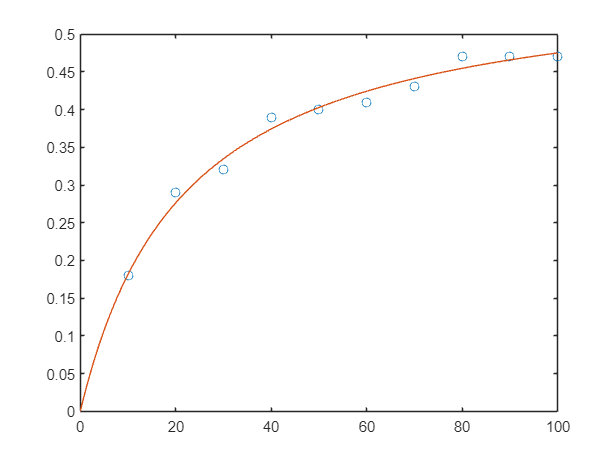


plot(x, y,'o',xx,yy,'-')

**Predict the value of y for the given x**

xtest = 45

xtest = 45


predict_y = alpha * xtest/(beta+xtest)

predict_y = 0.3896